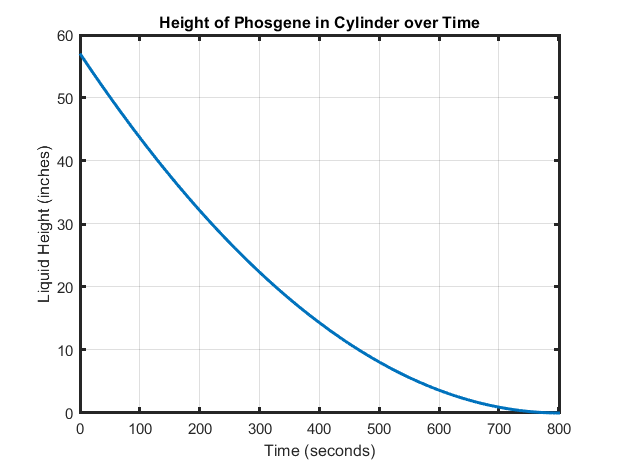

g = 386.09;
func = @(t) (sqrt(57.05)-(t*(0.61*0.5^2*sqrt(2*g))/(2*15^2))).^2;
plot(0:802,func(0:802),'LineWidth',2)
makePretty("Height of Phosgene in Cylinder over Time","Time (seconds)","Liquid Height (inches)")
xlim([0 802])

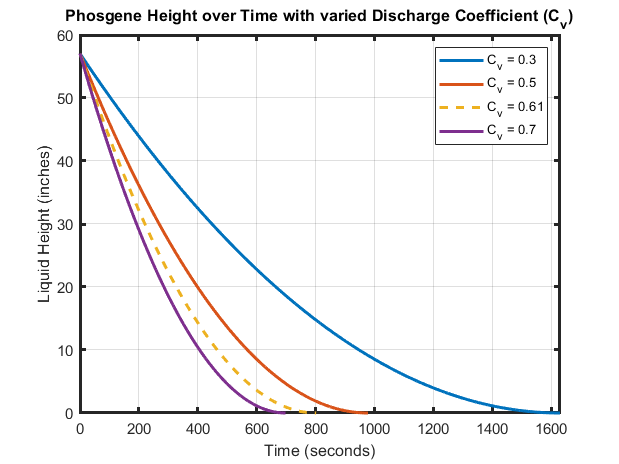

func = @(t,Cv) (sqrt(57.05)-(t*(Cv*0.5^2*sqrt(2*g))/(2*15^2))).^2;
figure
hold on
plot(0:1630,func(0:1630,0.3),'LineWidth',2)
plot(0:978,func(0:978,0.5),'LineWidth',2)
plot(0:802,func(0:802,0.61),'LineWidth',2,'LineStyle','--')
plot(0:698,func(0:698,0.7),'LineWidth',2)

xlim([0 1630])
legend(["C_v = 0.3", "C_v = 0.5", "C_v = 0.61", "C_v = 0.7"])
makePretty("Phosgene Height over Time with varied Discharge Coefficient (C_v)","Time (seconds)","Liquid Height (inches)")

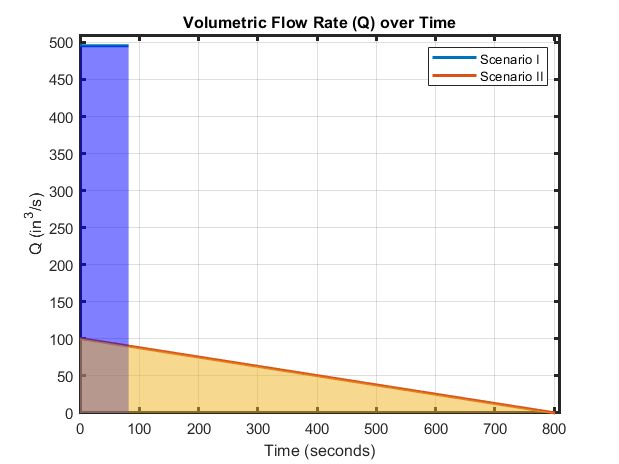

func1 = @(t) 495.47*t.^0;
func = @(t) pi*0.5^2*0.61*sqrt(2*g*(sqrt(57.05)-(t*(0.61*0.5^2*sqrt(2*g))/(2*15^2))).^2);
figure; hold on
plot(0:82,func1(0:82),'LineWidth',2)
plot(0:802,func(0:802),'LineWidth',2)
xlim([0 810])
ylim([0 510])
makePretty("Volumetric Flow Rate (Q) over Time","Time (seconds)","Q (in^3/s)")
legend(["Scenario I","Scenario II"])

a = area(0:82,func1(0:82),'FaceColor','b');
a.FaceAlpha = 0.5; a.EdgeColor = 'none';
set(get(get(a,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');

a = area(0:802,func(0:802),'FaceColor','#EDB120');
a.FaceAlpha = 0.5; a.EdgeColor = 'none';

set(get(get(a,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
integral(func1,0,82)

ans = 4.0629e+04

integral(func,0,802)

ans = 4.0326e+04